%% =========================================================
%  ROB_GRAPHS.M
%
%  Gráficos do estudo de robótica — lêem EXCLUSIVAMENTE do struct
%  RESULTS produzido por run_robot_stats(), SUS, SYS_EVAL, PERCEP,
%  COMP e robot_performance.
%
%  BLOCOS
%  ──────
%  ROB-2  Performance boxplots por grupo + pairwise sig lines
%         (Friedman + posthoc lidos de RESULTS.performance)
%
%  ROB-3  Success rate — barras agrupadas por grupo
%         + pairwise sig lines
%         (Cochran Q posthoc students; McNemar pairwise interns)
%         lidas de RESULTS.success
%
%  ROB-4  SUS Score — boxplots por grupo + sig lines
%         lidas de RESULTS.sus.friedman_students/interns + posthoc
%
%  ROB-5  SUS Items — spider chart Q1–Q10 por grupo
%         medianas de RESULTS.sus.items.item_N.descriptives
%
%  ROB-6  System Evaluation — spider chart 5 dims por grupo
%         medianas de RESULTS.syseval.<dim>.descriptives
%
%  ROB-7  Robot Perception — spider chart 6 dims por grupo
%         medianas de RESULTS.percep.<dim>.descriptives
%         (só robot_assist e robot_auto)
%
%  ROB-8  Comparative Preference — barras verticais agrupadas (%)
%         por grupo, lidas de RESULTS.comp.<dim>.freq
%
%  PRÉ-REQUISITOS no workspace:
%    RESULTS, SUS, SYS_EVAL, PERCEP, COMP,
%    robot_performance, stud_idx, int_idx
%% =========================================================


alpha = 0.05;


%% ── Paleta de cores (robot) ────────────────────────────────
col_rob  = [0.40 0.40 0.40;   % Human        — cinzento
            0.25 0.60 0.85;   % Robot Assist  — azul
            0.85 0.30 0.30];  % Robot Auto    — vermelho
col_perc = col_rob(2:3,:);    % Perception: Assist + Auto


%% ── Grupos ─────────────────────────────────────────────────
group_idxs   = {stud_idx, int_idx};
group_titles = {'Students', 'Interns'};
group_short  = {'students', 'interns'};


%% ── Métricas de performance ─────────────────────────────────
continuous_metrics = {'planning_time','puncture_time','distance_to_target','attempts'};
metric_ylabels     = {'Planning Time (s)','Puncture Time (s)',...
                      'Distance to Target (mm)','Number of Attempts'};


%% =========================================================
%  ROB-2 — Performance boxplots + pairwise sig lines
%
%  Dados:     robot_performance.(met)   [N x 3]  col: human | assist | auto
%  Friedman:  RESULTS.performance.(met).friedman_students / friedman_interns
%  Posthoc:   .posthoc (array de structs com .cond1, .cond2, .p_bonf)
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-2 — PERFORMANCE BOXPLOTS + PAIRWISE\n');

 ROB-2 — PERFORMANCE BOXPLOTS + PAIRWISE


fprintf('==================================================\n');

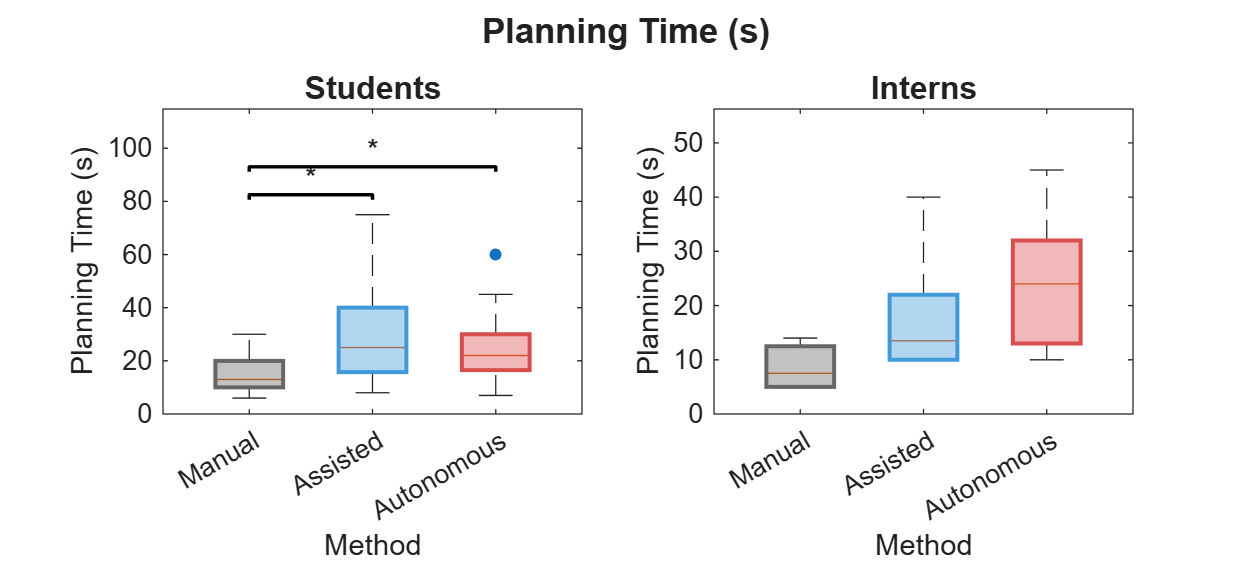

Figura guardada: rob_boxplot_planning_time_pairwise.pdf


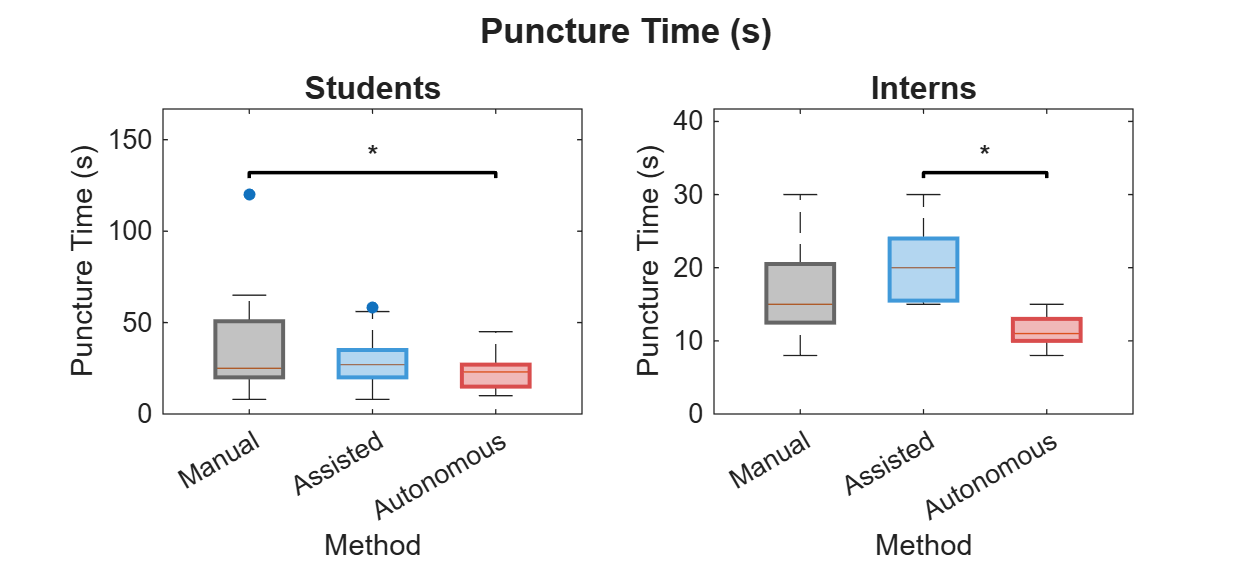

Figura guardada: rob_boxplot_puncture_time_pairwise.pdf


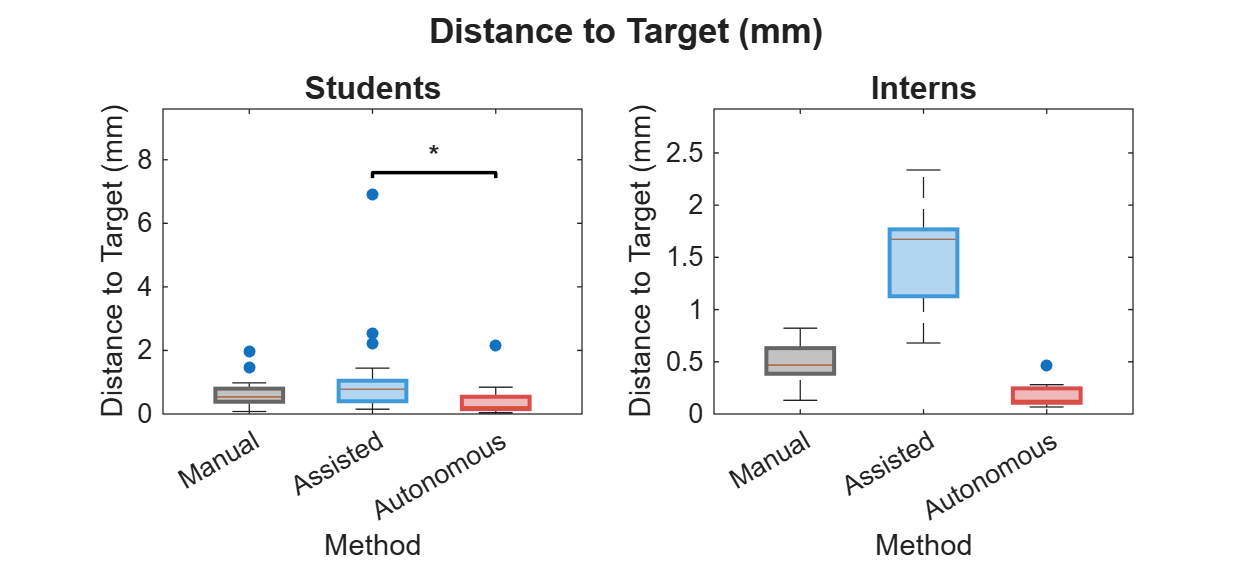

Figura guardada: rob_boxplot_distance_to_target_pairwise.pdf


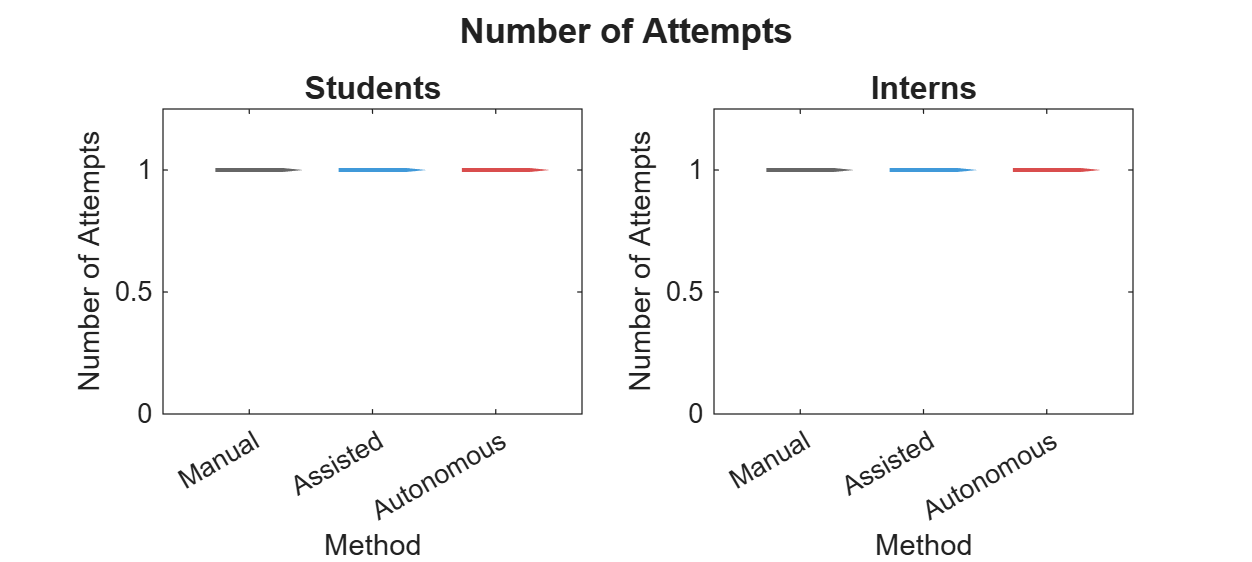

Figura guardada: rob_boxplot_attempts_pairwise.pdf




for mi = 1:numel(continuous_metrics)
    met = continuous_metrics{mi};
    X   = robot_performance.(met);   % [N x 3]: human | assist | auto
    R   = RESULTS.performance.(met);


    fig = figure('Name',sprintf('Rob_%s_pairwise',met), ...
        'Units','centimeters','Position',[2 2 20 9],'Color','white');


    for gi = 1:2
        idx = group_idxs{gi};
        ax  = subplot(1,2,gi);
        hold(ax,'on'); box(ax,'on');


        % 1. Boxplots
        all_vals = [];
        for m = 1:3
            col_d = X(idx,m); col_d = col_d(~isnan(col_d));
            all_vals = [all_vals; col_d]; %#ok<AGROW>
            if isempty(col_d), continue; end
            bp    = boxplot(ax, col_d, 'Positions', m, 'Widths', 0.55, ...
                'Symbol','o','OutlierSize',4);
            h_box = findobj(bp,'Tag','Box');
            patch(ax, get(h_box,'XData'), get(h_box,'YData'), col_rob(m,:), ...
                'FaceAlpha',0.4,'EdgeColor',col_rob(m,:),'LineWidth',1.5);
        end
        if isempty(all_vals), continue; end
        y_data = max(all_vals);
        gap    = y_data * 0.10;
        y_cur  = y_data + gap;


        % 2. Sig lines — ler de RESULTS
        if gi == 1
            fr_key = 'friedman_students';
        else
            fr_key = 'friedman_interns';
        end

        if isfield(R, fr_key) && isfield(R.(fr_key),'p') && ...
           ~isnan(R.(fr_key).p) && R.(fr_key).p < alpha && ...
           isfield(R.(fr_key),'posthoc')
            ph = R.(fr_key).posthoc;
            for pi = 1:numel(ph)
                p_pair = ph(pi).p_bonf;
                if isnan(p_pair) || p_pair >= alpha, continue; end
                m1 = rob_cond_to_idx(ph(pi).cond1);
                m2 = rob_cond_to_idx(ph(pi).cond2);
                if m1==0 || m2==0, continue; end
                draw_sig_bracket(ax, m1, m2, y_cur, gap, p_pair);
                y_cur = y_cur + gap*1.4;
            end
        end


        % 3. Axes
        ylim(ax, [0, y_cur + gap*1.5]);
        xlim(ax, [0.3 3.7]);
        set(ax,'XTick',1:3,'XTickLabel',{'Manual','Assisted','Autonomous'},'FontSize',10);
        xlabel(ax,'Method','FontSize',11);
        ylabel(ax,metric_ylabels{mi},'FontSize',11);
        title(ax, group_titles{gi},'FontSize',12,'FontWeight','bold');
    end


    sgtitle(fig, metric_ylabels{mi},'FontSize',13,'FontWeight','bold');
    exportgraphics(fig, sprintf('rob_boxplot_%s_pairwise.pdf',met), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: rob_boxplot_%s_pairwise.pdf\n', met);
end



%% =========================================================
%  ROB-3 — Success rate — barras agrupadas + pairwise
%
%  Dados:    robot_performance.success   [N x 3]
%  Students: RESULTS.success.cochranq_students.p + .posthoc
%  Interns:  RESULTS.success.mcnemar_interns.human_vs_assist /
%                                         .human_vs_auto /
%                                         .assist_vs_auto
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-3 — SUCCESS RATE BARRAS + PAIRWISE\n');

 ROB-3 — SUCCESS RATE BARRAS + PAIRWISE


fprintf('==================================================\n');

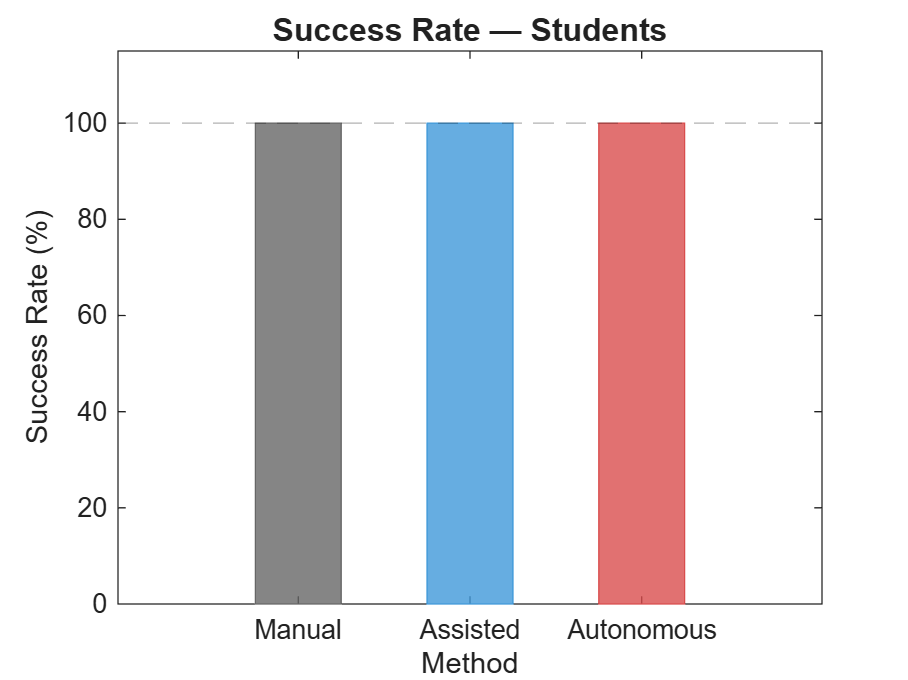

Figura guardada: rob_success_students.pdf


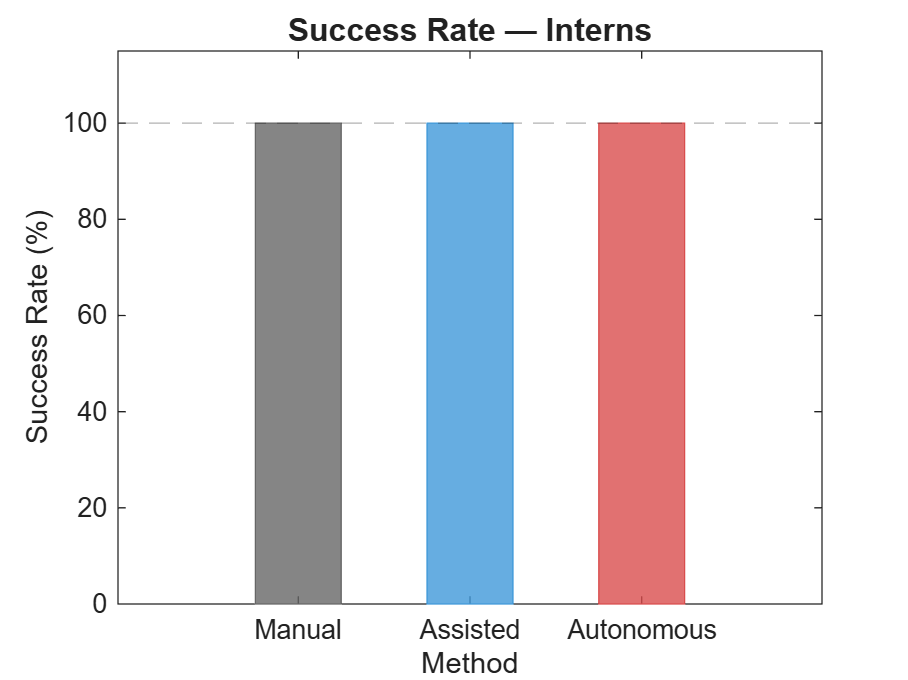

Figura guardada: rob_success_interns.pdf




S_rob  = robot_performance.success;
RS_suc = RESULTS.success;


for gi = 1:2
    idx = group_idxs{gi};


    fig = figure('Name',sprintf('Rob_success_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 12 9],'Color','white');
    ax  = axes(fig); hold(ax,'on'); box(ax,'on');


    pcts = zeros(1,3);
    for m = 1:3
        col_d = S_rob(idx,m); valid = ~isnan(col_d);
        if sum(valid) > 0
            pcts(m) = 100 * sum(col_d(valid)) / sum(valid);
        end
        bh = bar(ax, m, pcts(m), 'BarWidth', 0.5);
        bh.FaceColor = col_rob(m,:); bh.FaceAlpha = 0.8;
        bh.EdgeColor = col_rob(m,:);
    end


    y_max = max(pcts);
    gap   = 5;
    y_cur = y_max + gap*1.5;


    if gi == 1
        % Students — Cochran Q posthoc
        if isfield(RS_suc,'cochranq_students') && ...
           isfield(RS_suc.cochranq_students,'p') && ...
           ~isnan(RS_suc.cochranq_students.p) && ...
           RS_suc.cochranq_students.p < alpha && ...
           isfield(RS_suc.cochranq_students,'posthoc')
            ph = RS_suc.cochranq_students.posthoc;
            for pi = 1:numel(ph)
                p_pair = ph(pi).p_bonf;
                if isnan(p_pair) || p_pair >= alpha, continue; end
                m1 = rob_cond_to_idx(ph(pi).cond1);
                m2 = rob_cond_to_idx(ph(pi).cond2);
                if m1==0 || m2==0, continue; end
                draw_sig_bracket(ax, m1, m2, y_cur, gap, p_pair);
                y_cur = y_cur + gap*1.6;
            end
        end
    else
        % Interns — McNemar pairwise
        pairs_mc = { ...
            'human_vs_assist', 1, 2; ...
            'human_vs_auto',   1, 3; ...
            'assist_vs_auto',  2, 3};
        np_mc = size(pairs_mc,1);
        for pi = 1:np_mc
            fkey = pairs_mc{pi,1};
            m1   = pairs_mc{pi,2};
            m2   = pairs_mc{pi,3};
            if ~isfield(RS_suc,'mcnemar_interns') || ...
               ~isfield(RS_suc.mcnemar_interns, fkey), continue; end
            p_mc = RS_suc.mcnemar_interns.(fkey).p;
            p_bonf = min(p_mc * np_mc, 1);
            if isnan(p_bonf) || p_bonf >= alpha, continue; end
            draw_sig_bracket(ax, m1, m2, y_cur, gap, p_bonf);
            y_cur = y_cur + gap*1.6;
        end
    end


    ylim(ax, [0 min(y_cur + gap*2, 115)]);
    yline(ax, 100,'--k','Alpha',0.3);
    set(ax,'XTick',1:3,'XTickLabel',{'Manual','Assisted','Autonomous'},'FontSize',10);
    xlabel(ax,'Method','FontSize',11);
    ylabel(ax,'Success Rate (%)','FontSize',11);
    title(ax, sprintf('Success Rate — %s',group_titles{gi}), ...
        'FontSize',12,'FontWeight','bold');


    exportgraphics(fig, sprintf('rob_success_%s.pdf',group_short{gi}), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: rob_success_%s.pdf\n', group_short{gi});
end



%% =========================================================
%  ROB-4 — SUS Score — boxplots + sig lines por grupo
%
%  Dados:    SUS.human.score / SUS.robot_assist.score / SUS.robot_auto.score
%  Friedman: RESULTS.sus.friedman_students / friedman_interns
%  Posthoc:  .posthoc (array com .cond1, .cond2, .p_bonf)
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-4 — SUS SCORE BOXPLOTS + PAIRWISE\n');

 ROB-4 — SUS SCORE BOXPLOTS + PAIRWISE


fprintf('==================================================\n');

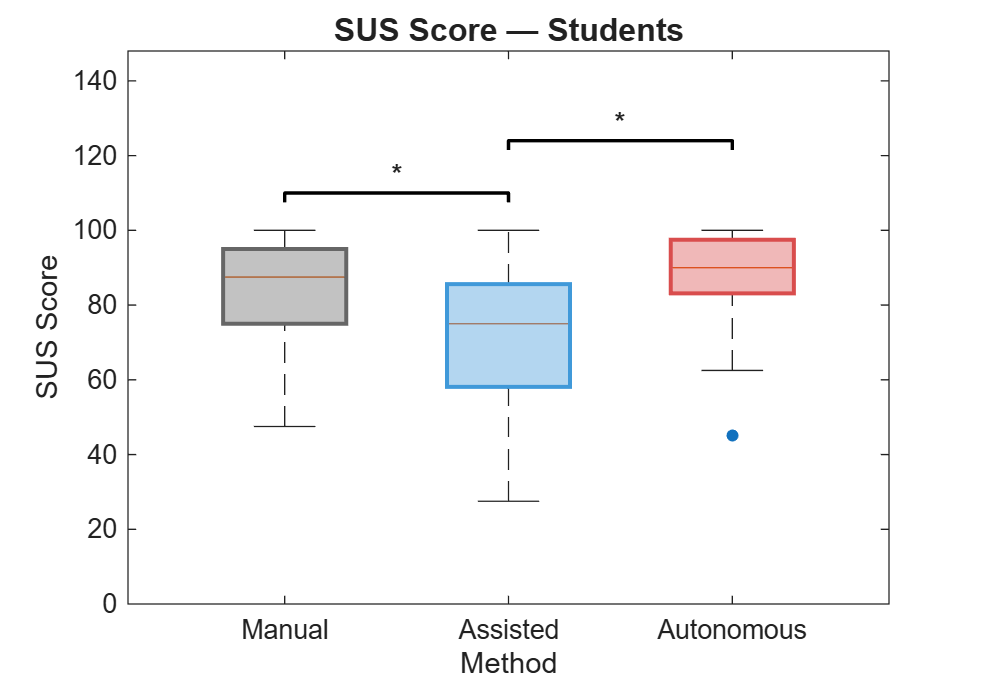

Figura guardada: rob_SUS_score_students.pdf


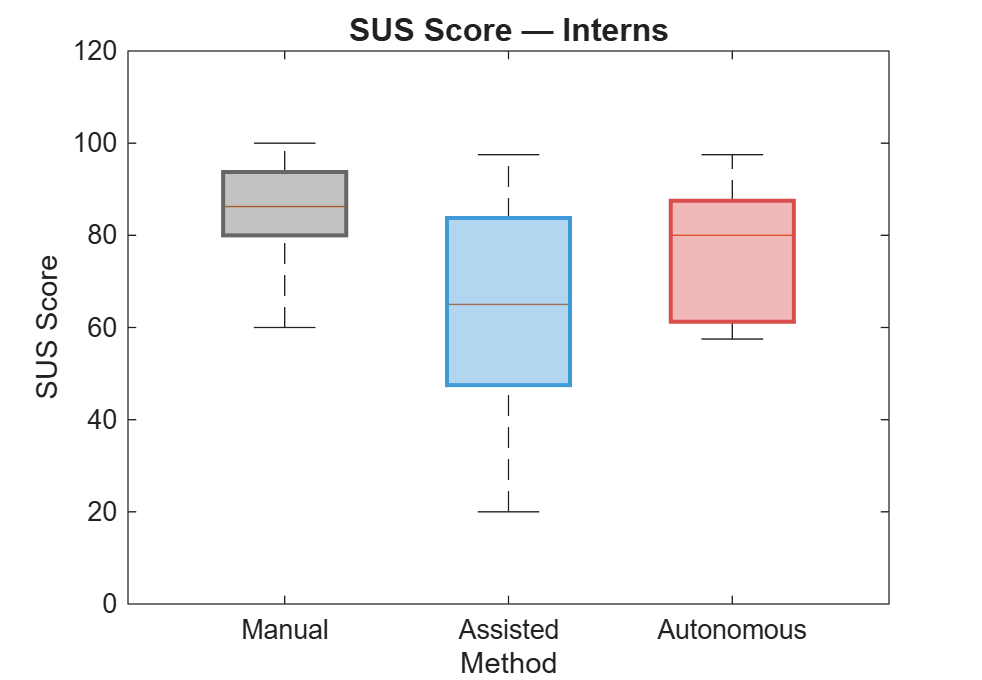

Figura guardada: rob_SUS_score_interns.pdf




sus_keys = {'human','robot_assist','robot_auto'};
RS_sus   = RESULTS.sus;


for gi = 1:2
    idx = group_idxs{gi};
    D   = [SUS.human.score(idx), SUS.robot_assist.score(idx), SUS.robot_auto.score(idx)];


    fig = figure('Name',sprintf('Rob_SUS_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 9],'Color','white');
    ax  = axes(fig);
    hold(ax,'on'); box(ax,'on');


    all_v = [];
    for m = 1:3
        col_d = D(:,m); col_d = col_d(~isnan(col_d));
        all_v = [all_v; col_d]; %#ok<AGROW>
        if isempty(col_d), continue; end
        bp    = boxplot(ax, col_d,'Positions',m,'Widths',0.55,'Symbol','o','OutlierSize',4);
        h_box = findobj(bp,'Tag','Box');
        patch(ax, get(h_box,'XData'), get(h_box,'YData'), col_rob(m,:), ...
            'FaceAlpha',0.4,'EdgeColor',col_rob(m,:),'LineWidth',1.5);
    end
    y_data = max(all_v);
    gap    = y_data * 0.10;
    y_cur  = y_data + gap;


    if gi == 1
        fr_key = 'friedman_students';
    else
        fr_key = 'friedman_interns';
    end

    if isfield(RS_sus, fr_key) && isfield(RS_sus.(fr_key),'p') && ...
       ~isnan(RS_sus.(fr_key).p) && RS_sus.(fr_key).p < alpha && ...
       isfield(RS_sus.(fr_key),'posthoc')
        ph = RS_sus.(fr_key).posthoc;
        for pi = 1:numel(ph)
            p_pair = ph(pi).p_bonf;
            if isnan(p_pair) || p_pair >= alpha, continue; end
            m1 = rob_cond_to_idx(ph(pi).cond1);
            m2 = rob_cond_to_idx(ph(pi).cond2);
            if m1==0 || m2==0, continue; end
            draw_sig_bracket(ax, m1, m2, y_cur, gap, p_pair);
            y_cur = y_cur + gap*1.4;
        end
    end


    ylim(ax, [0, y_cur + gap]);
    xlim(ax, [0.3 3.7]);
    set(ax,'XTick',1:3,'XTickLabel',{'Manual','Assisted','Autonomous'},'FontSize',10);
    xlabel(ax,'Method','FontSize',11);
    ylabel(ax,'SUS Score','FontSize',11);
    title(ax, sprintf('SUS Score — %s',group_titles{gi}), ...
        'FontSize',12,'FontWeight','bold');


    exportgraphics(fig, sprintf('rob_SUS_score_%s.pdf',group_short{gi}), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: rob_SUS_score_%s.pdf\n', group_short{gi});
end



%% =========================================================
%  ROB-5 — SUS Items — spider chart Q1–Q10 por grupo
%  Medianas de RESULTS.sus.items.item_N.descriptives.(group).(method).median
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-5 — SPIDER CHART SUS POR ITEM\n');

 ROB-5 — SPIDER CHART SUS POR ITEM


fprintf('==================================================\n');

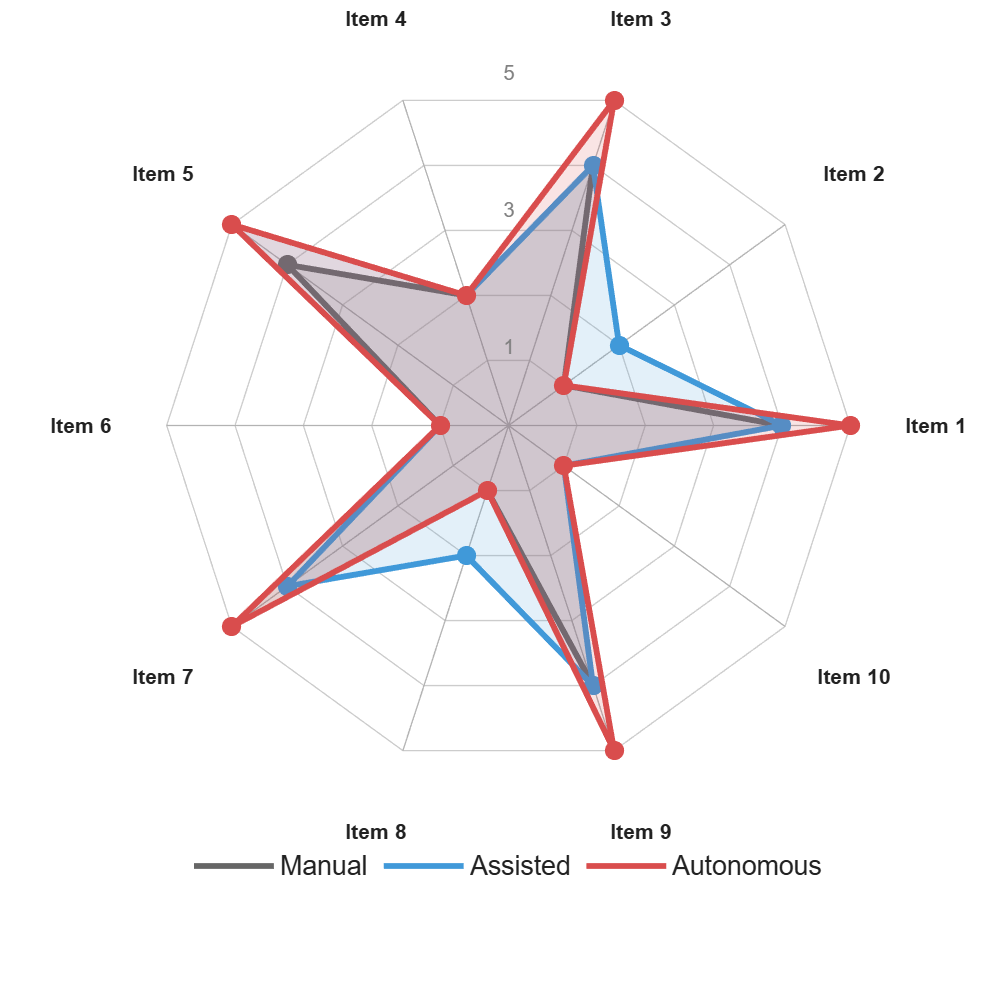

Figura guardada: rob_SUS_spider_students.pdf


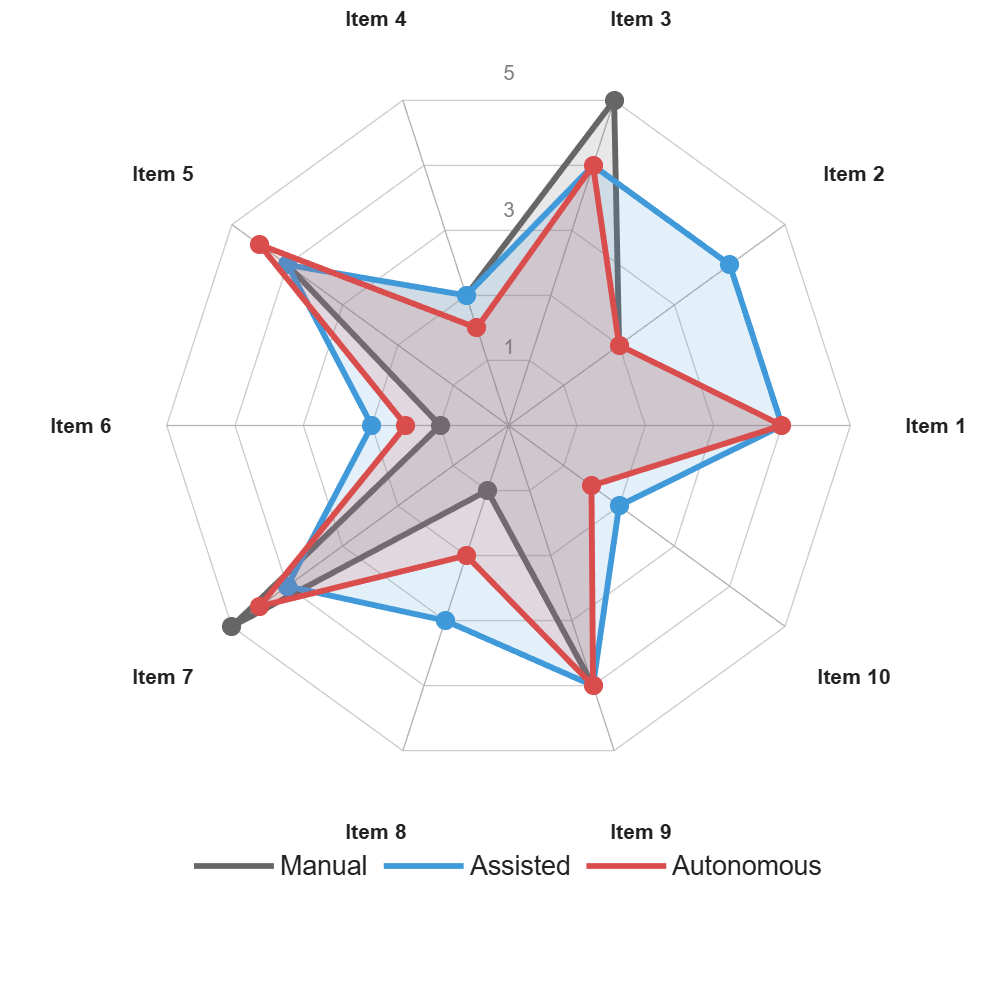

Figura guardada: rob_SUS_spider_interns.pdf




sus_item_labels = {'Item 1','Item 2','Item 3','Item 4','Item 5',...
                   'Item 6','Item 7','Item 8','Item 9','Item 10'};


for gi = 1:2
    grp_key = group_short{gi};
    nd = 10;
    D  = zeros(nd, 3);


    for it = 1:nd
        iname = sprintf('item_%d', it);
        if ~isfield(RESULTS.sus.items, iname), continue; end
        desc = RESULTS.sus.items.(iname).descriptives;
        mkeys = {'human','robot_assist','robot_auto'};
        for m = 1:3
            try
                D(it,m) = desc.(grp_key).(mkeys{m}).median;
            catch
                D(it,m) = NaN;
            end
        end
    end


    fig = figure('Name',sprintf('Rob_SUS_spider_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 13],'Color','white');
    ax = axes(fig); hold(ax,'on');
    h_lines = draw_radar_rob(ax, D, sus_item_labels, col_rob, 5);


    legend(ax, h_lines, {'Manual','Assisted','Autonomous'}, ...
        'Location','southoutside','Orientation','horizontal','FontSize',10,'Box','off');
    %title(ax, sprintf('SUS Items — %s',group_titles{gi}), ...
     %   'FontSize',12,'FontWeight','bold');


    exportgraphics(fig, sprintf('rob_SUS_spider_%s.pdf',group_short{gi}), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: rob_SUS_spider_%s.pdf\n', group_short{gi});
end



%% =========================================================
%  ROB-6 — System Evaluation — spider chart por grupo
%  5 dimensões: safe, precise, mental_effort, confidence, satisfaction
%  Medianas de RESULTS.syseval.<dim>.descriptives.(group).(method).median
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-6 — SPIDER CHART SYSTEM EVALUATION\n');

 ROB-6 — SPIDER CHART SYSTEM EVALUATION


fprintf('==================================================\n');

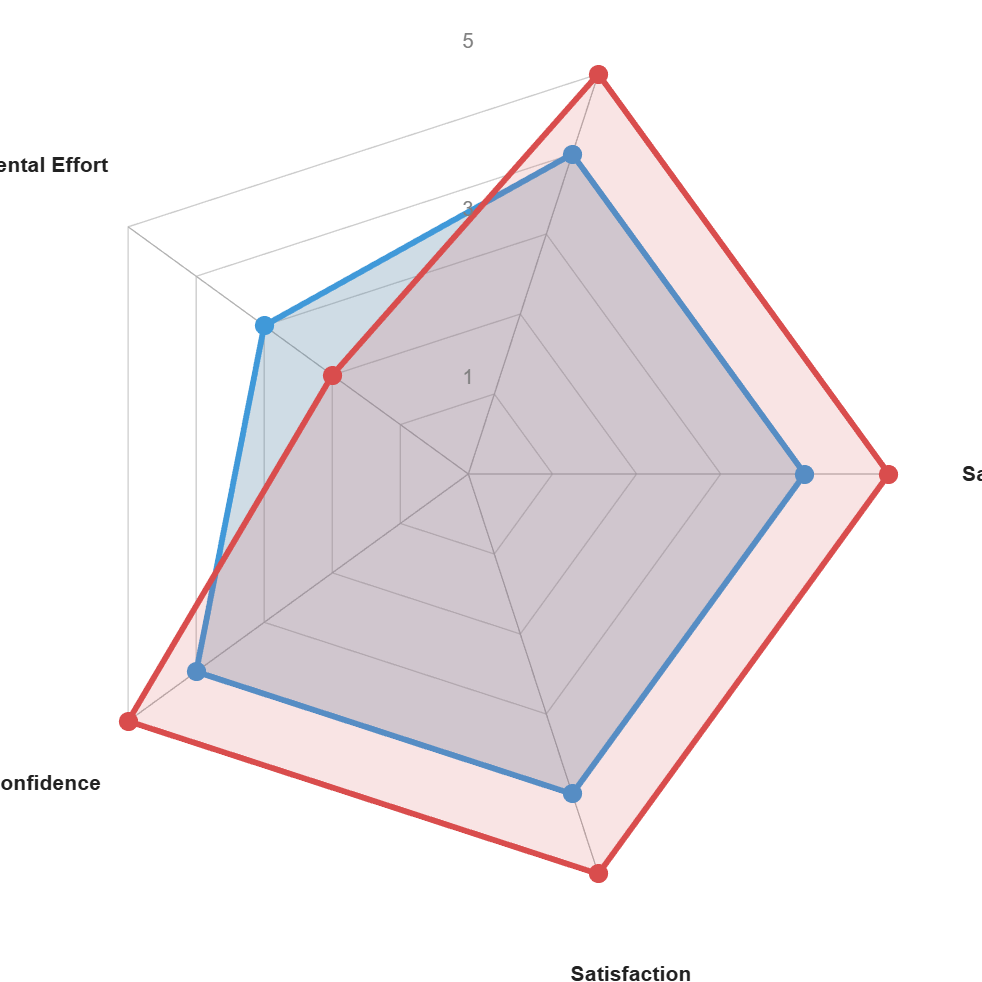

Figura guardada: rob_syseval_spider_students.pdf


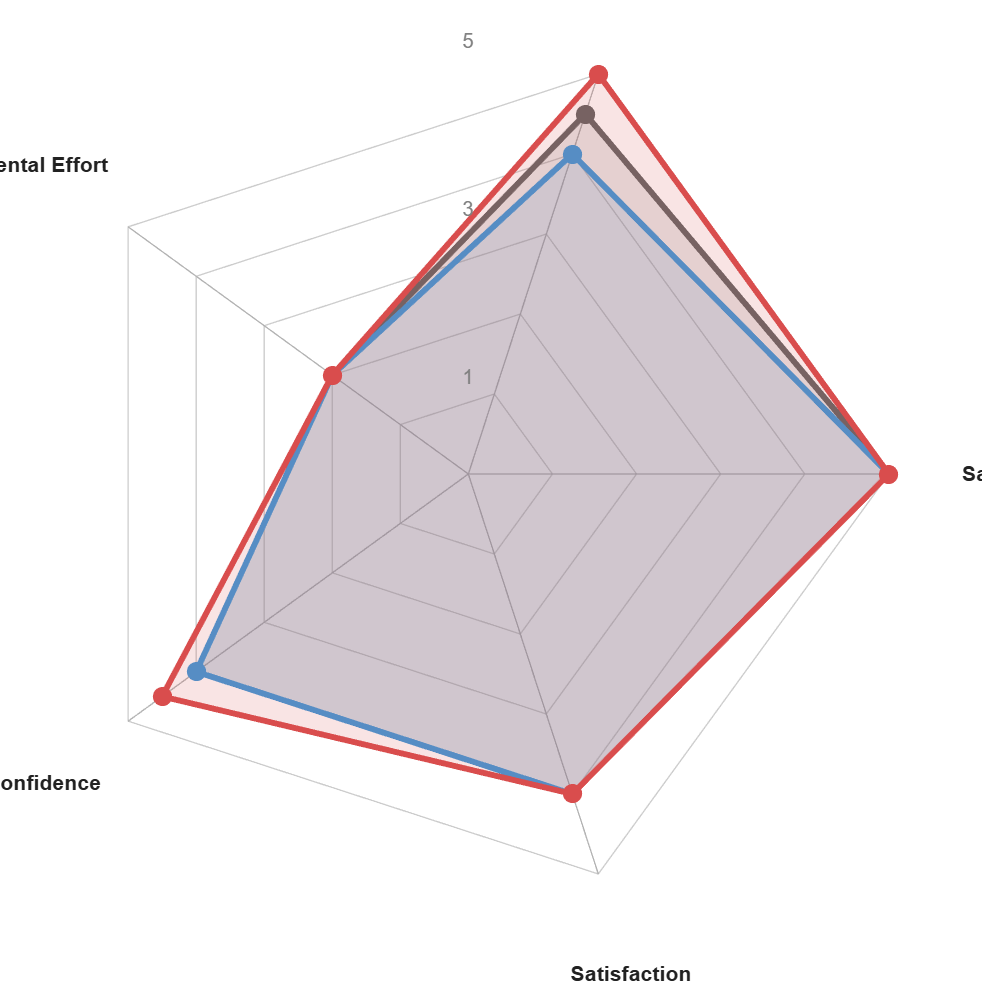

Figura guardada: rob_syseval_spider_interns.pdf




sys_dims_rob = {'safe','precise','mental_effort','confidence','satisfaction'};
sys_lbl_rob  = {'Safety','Precision','Mental Effort','Confidence','Satisfaction'};
sys_mkeys    = {'human','robot_assist','robot_auto'};


for gi = 1:2
    grp_key = group_short{gi};
    nd = numel(sys_dims_rob);
    D  = zeros(nd, 3);


    for d = 1:nd
        for m = 1:3
            try
                D(d,m) = RESULTS.syseval.(sys_dims_rob{d}).descriptives.(grp_key).(sys_mkeys{m}).median;
            catch
                D(d,m) = NaN;
            end
        end
    end


    fig = figure('Name',sprintf('Rob_syseval_spider_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 13],'Color','white');
    ax = axes(fig); hold(ax,'on');
    h_lines = draw_radar_rob(ax, D, sys_lbl_rob, col_rob, 5);


    %legend(ax, h_lines, {'Manual','Assisted','Autonomous'}, ...
     %   'Location','southoutside','Orientation','horizontal','FontSize',10,'Box','off');
    %title(ax, sprintf('System Evaluation — %s',group_titles{gi}), ...
     %   'FontSize',12,'FontWeight','bold');


    fname = sprintf('rob_syseval_spider_%s.pdf',group_short{gi});
    exportgraphics(fig, fname,'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: %s\n', fname);
end



%% =========================================================
%  ROB-7 — Robot Perception — spider chart por grupo
%  6 dimensões: confortable, safety_measures, control,
%               reproducibility, clinic_use, autonomy
%  Só robot_assist e robot_auto (col_perc)
%  Medianas de RESULTS.percep.<dim>.descriptives.(group).(method).median
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-7 — SPIDER CHART ROBOT PERCEPTION\n');

 ROB-7 — SPIDER CHART ROBOT PERCEPTION


fprintf('==================================================\n');

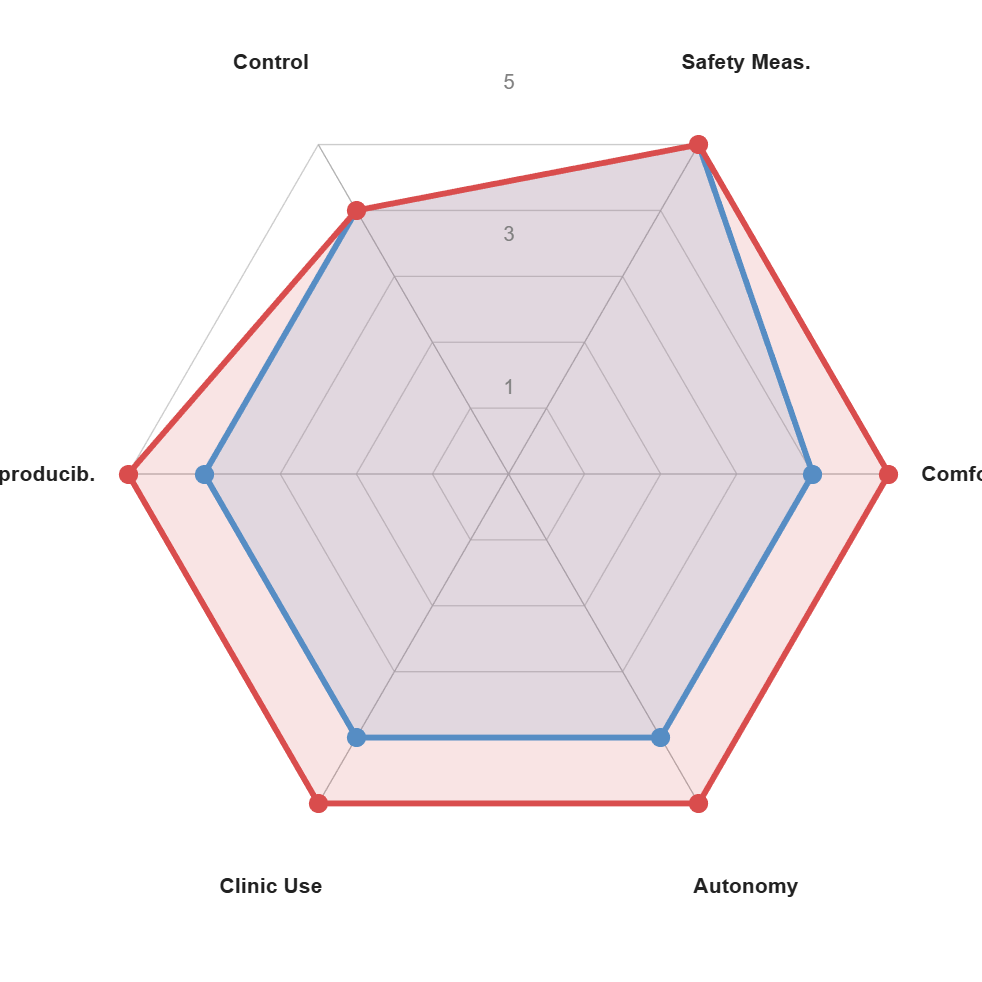

Figura guardada: rob_percep_spider_students.pdf


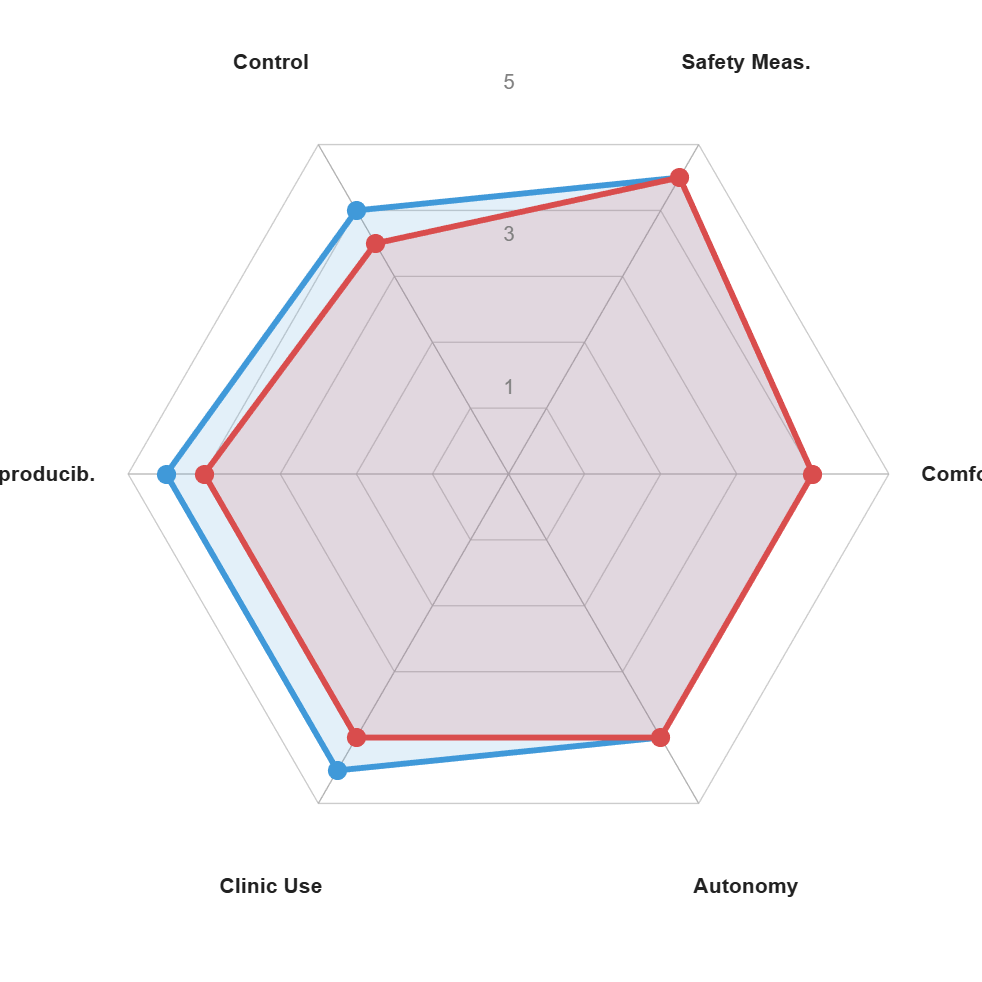

Figura guardada: rob_percep_spider_interns.pdf




perc_dims_rob = {'confortable','safety_measures','control',...
                 'reproducibility','clinic_use','autonomy'};
perc_lbl_rob  = {'Comfortable','Safety Meas.','Control',...
                 'Reproducib.','Clinic Use','Autonomy'};
perc_mkeys    = {'robot_assist','robot_auto'};


for gi = 1:2
    grp_key = group_short{gi};
    nd = numel(perc_dims_rob);
    D  = zeros(nd, 2);


    for d = 1:nd
        for m = 1:2
            try
                D(d,m) = RESULTS.percep.(perc_dims_rob{d}).descriptives.(grp_key).(perc_mkeys{m}).median;
            catch
                D(d,m) = NaN;
            end
        end
    end


    fig = figure('Name',sprintf('Rob_percep_spider_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 13 13],'Color','white');
    ax = axes(fig); hold(ax,'on');
    h_lines = draw_radar_rob(ax, D, perc_lbl_rob, col_perc, 5);


    %legend(ax, h_lines, {'Assisted','Autonomous'}, ...
     %   'Location','southoutside','Orientation','horizontal','FontSize',10,'Box','off');
    %title(ax, sprintf('Robot Perception — %s',group_titles{gi}), ...
     %   'FontSize',12,'FontWeight','bold');


    fname = sprintf('rob_percep_spider_%s.pdf',group_short{gi});
    exportgraphics(fig, fname,'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: %s\n', fname);
end



%% =========================================================
%  ROB-8 — Comparative Preference — barras verticais agrupadas
%  4 dimensões: precision, safe, global_preference, clinic_use
%  % por método, lidas de RESULTS.comp.<dim>.freq.(group)
%% =========================================================
fprintf('\n==================================================\n');

fprintf(' ROB-8 — PREFERENCE GROUPED BARS\n');

 ROB-8 — PREFERENCE GROUPED BARS


fprintf('==================================================\n');

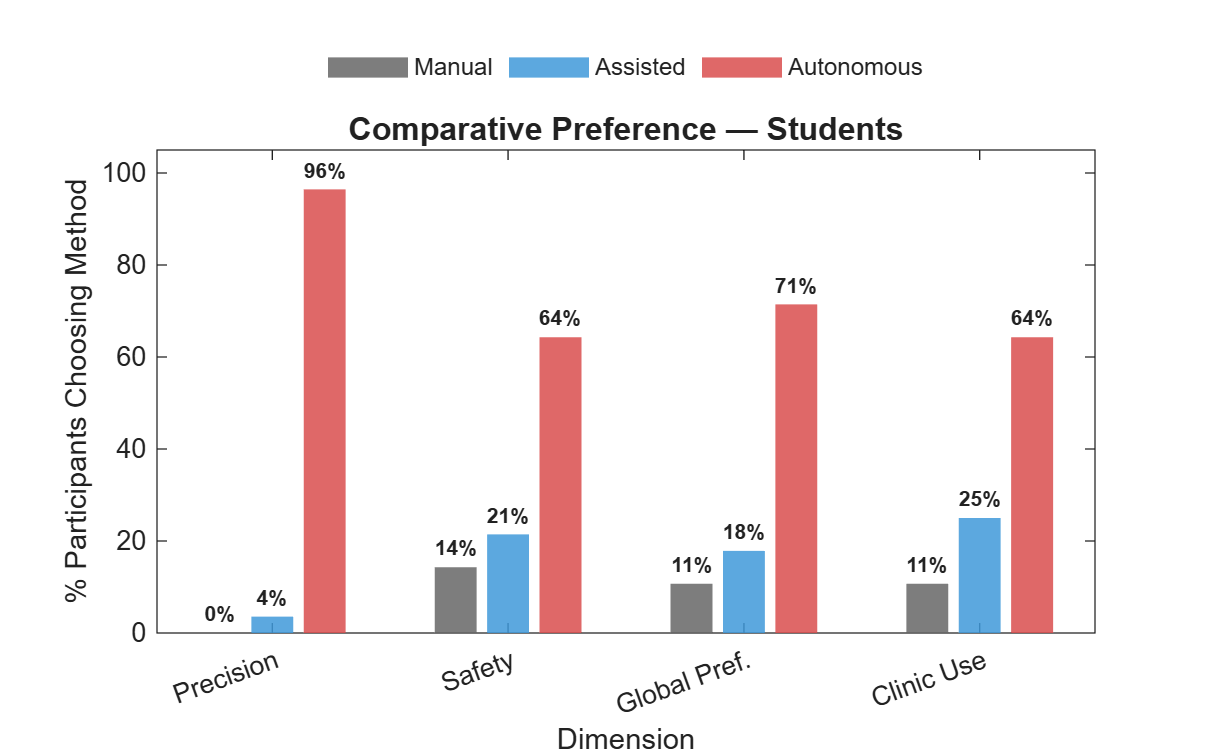

Figura guardada: rob_preference_bars_students.pdf


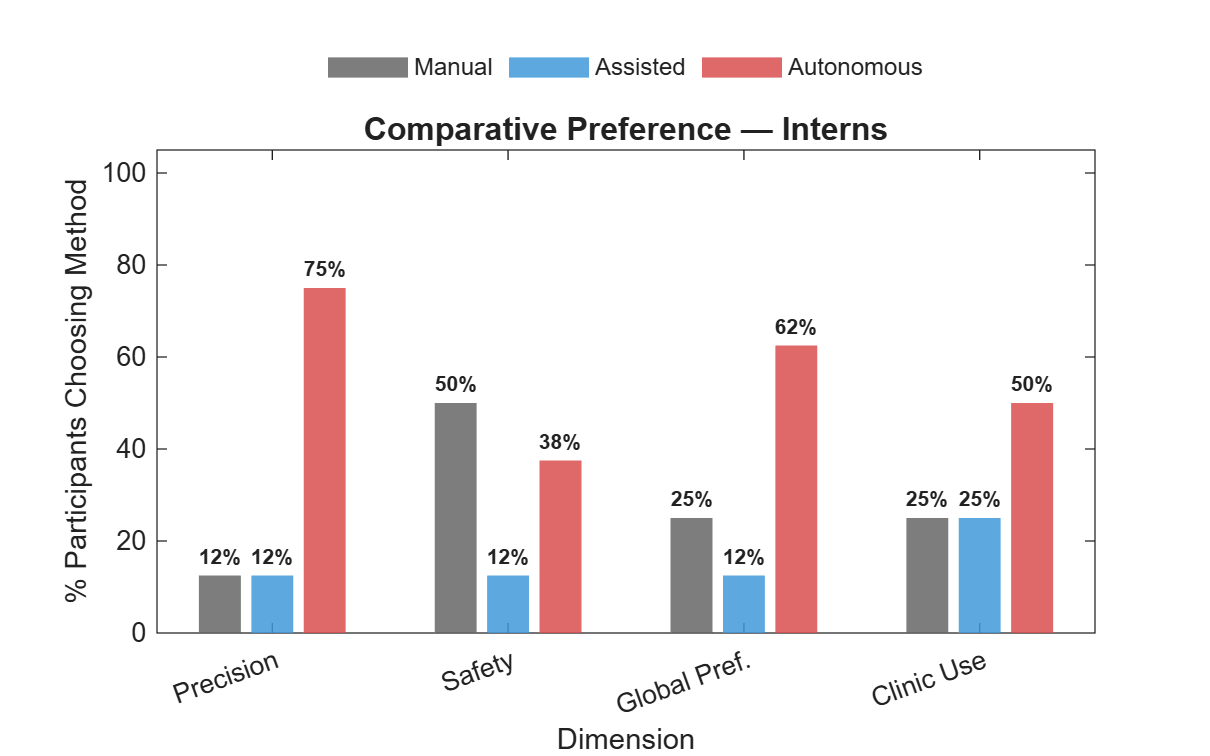

Figura guardada: rob_preference_bars_interns.pdf


 
 
comp_dims_rob = {'precision','safe','global_preference','clinic_use'};
comp_lbl_rob  = {'Precision','Safety','Global Pref.','Clinic Use'};
comp_mkeys    = {'human','robot_assist','robot_auto'};
 
 
for gi = 1:2
    grp_key = group_short{gi};
    nd = numel(comp_dims_rob);
    pct_mat = zeros(nd, 3);
 
 
    for d = 1:nd
        dim = comp_dims_rob{d};
        if ~isfield(RESULTS.comp, dim) || ~isfield(RESULTS.comp.(dim),'freq'), continue; end
        freq = RESULTS.comp.(dim).freq;
        if ~isfield(freq, grp_key), continue; end
        grp_freq = freq.(grp_key);
        % estrutura: grp_freq.counts [1x3], grp_freq.pct [1x3]
        if isfield(grp_freq,'pct') && numel(grp_freq.pct) == 3
            pct_mat(d,:) = grp_freq.pct;
        elseif isfield(grp_freq,'counts') && numel(grp_freq.counts) == 3 && ...
               isfield(grp_freq,'n') && grp_freq.n > 0
            pct_mat(d,:) = 100 * grp_freq.counts / grp_freq.n;
        end
    end
 
 
    fig = figure('Name',sprintf('Rob_preference_bars_%s',group_short{gi}), ...
        'Units','centimeters','Position',[2 2 16 10],'Color','white');
    ax = axes(fig);
    hold(ax,'on'); box(ax,'on');
 
 
    b = bar(ax, 1:nd, pct_mat, 'grouped');
    for m = 1:3
        b(m).FaceColor = col_rob(m,:);
        b(m).FaceAlpha = 0.85;
        b(m).EdgeColor = 'none';
    end
 
 
    % Labels de percentagem em cima de cada barra
    for m = 1:3
        xtips  = b(m).XEndPoints;
        ytips  = b(m).YEndPoints;
        labels = compose('%.0f%%', b(m).YData);
        text(ax, xtips, ytips+1.5, labels, ...
            'HorizontalAlignment','center','VerticalAlignment','bottom', ...
            'FontSize',8,'FontWeight','bold');
    end
 
 
    legend(ax, b, {'Manual','Assisted','Autonomous'}, ...
        'Location','northoutside','Orientation','horizontal','FontSize',9,'Box','off');
    set(ax,'XTick',1:nd,'XTickLabel',comp_lbl_rob, ...
        'XTickLabelRotation',20,'FontSize',10,'YLim',[0 105]);
    ylabel(ax,'% Participants Choosing Method','FontSize',11);
    xlabel(ax,'Dimension','FontSize',11);
    title(ax, sprintf('Comparative Preference — %s',group_titles{gi}), ...
        'FontSize',12,'FontWeight','bold');
 
 
    exportgraphics(fig, sprintf('rob_preference_bars_%s.pdf',group_short{gi}), ...
        'ContentType','vector','BackgroundColor','white');
    fprintf('Figura guardada: rob_preference_bars_%s.pdf\n', group_short{gi});
end

 

fprintf('\n\n========== ROB_GRAPHS COMPLETO ==========\n');



========== ROB_GRAPHS COMPLETO ==========


fprintf('Ficheiros gerados:\n');

Ficheiros gerados:


fprintf('  rob_boxplot_<metric>_pairwise.pdf   x4\n');

  rob_boxplot_<metric>_pairwise.pdf   x4


fprintf('  rob_success_students/interns.pdf\n');

  rob_success_students/interns.pdf


fprintf('  rob_SUS_score_students/interns.pdf\n');

  rob_SUS_score_students/interns.pdf


fprintf('  rob_SUS_spider_students/interns.pdf\n');

  rob_SUS_spider_students/interns.pdf


fprintf('  rob_syseval_spider_students/interns.pdf\n');

  rob_syseval_spider_students/interns.pdf


fprintf('  rob_percep_spider_students/interns.pdf\n');

  rob_percep_spider_students/interns.pdf


fprintf('  rob_preference_bars_students/interns.pdf\n');

  rob_preference_bars_students/interns.pdf




%% =========================================================
%  FUNÇÕES LOCAIS AUXILIARES
%% =========================================================


% draw_radar_rob — radar/spider chart
% data_matrix: [nd x nm]  — nd dimensões, nm métodos
% dim_labels:  cell {nd}
% colors:      [nm x 3]   — uma cor por método
% max_val:     máximo da escala (5 para likert)
% Devolve h_lines [nm x 1] para usar na legenda
function h_lines = draw_radar_rob(ax, data_matrix, dim_labels, colors, max_val)
    [nd, nm] = size(data_matrix);
    angles   = linspace(0, 2*pi, nd+1);


    % Anéis e raios de fundo
    for r = 1:max_val
        xr = r/max_val * cos(angles);
        yr = r/max_val * sin(angles);
        plot(ax,[xr xr(1)],[yr yr(1)],'Color',[0.8 0.8 0.8],'LineWidth',0.5);
    end
    for d = 1:nd
        line(ax,[0 cos(angles(d))],[0 sin(angles(d))], ...
            'Color',[0.7 0.7 0.7],'LineWidth',0.5);
    end


    % Polígonos por método
    h_lines = gobjects(nm,1);
    for m = 1:nm
        vals = data_matrix(:,m) / max_val;
        xv   = vals .* cos(angles(1:nd))';
        yv   = vals .* sin(angles(1:nd))';
        xv(end+1) = xv(1); yv(end+1) = yv(1); %#ok<AGROW>
        h_lines(m) = plot(ax,xv,yv,'Color',colors(m,:),'LineWidth',2.2);
        fill(ax,xv,yv,colors(m,:),'FaceAlpha',0.15,'EdgeColor','none');
        scatter(ax,xv(1:nd),yv(1:nd),45,colors(m,:),'filled', ...
            'MarkerEdgeColor',colors(m,:));
    end


    % Labels das dimensões
    label_r = 1.25;
    for d = 1:nd
        text(ax, label_r*cos(angles(d)), label_r*sin(angles(d)), dim_labels{d}, ...
            'HorizontalAlignment','center','FontSize',8,'FontWeight','bold');
    end


    % Labels dos anéis
    ring_vals = unique([1, round(max_val/2), max_val]);
    for r = ring_vals
        text(ax, 0, r/max_val+0.03, num2str(r), ...
            'HorizontalAlignment','center','FontSize',7.5,'Color',[0.5 0.5 0.5]);
    end


    axis(ax,'equal','off');
end


% rob_cond_to_idx — converte label de condição para índice de coluna
% 'Human'→1 / 'human'→1, 'Robot Assist'→2 / 'robot_assist'→2,
% 'Robot Auto'→3 / 'robot_auto'→3
function idx = rob_cond_to_idx(lbl)
    lbl = strtrim(lower(lbl));
    % normalizar: remover espaços e underscores para comparação simples
    lbl = strrep(lbl,' ','_');
    if     contains(lbl,'human') && ~contains(lbl,'assist') && ~contains(lbl,'auto')
        idx = 1;
    elseif contains(lbl,'assist')
        idx = 2;
    elseif contains(lbl,'auto')
        idx = 3;
    else
        idx = 0;
    end
end


% sig_star — p-value → asteriscos APA
function lbl = sig_star(p)
    if     p < 0.05,  lbl = '*';
    else,             lbl = 'ns';
    end
end


% draw_sig_bracket — linha de significância entre dois pontos x
function draw_sig_bracket(ax, x1, x2, y, gap, p_bonf)
    if isnan(p_bonf) || p_bonf >= 0.05, return; end
    tk = gap * 0.25;
    line(ax,[x1 x1 x2 x2],[y-tk y y y-tk], ...
        'Color','k','LineWidth',1.3,'Clipping','off');
    text(ax,(x1+x2)/2, y+tk*0.3, sig_star(p_bonf), ...
        'HorizontalAlignment','center','VerticalAlignment','bottom', ...
        'FontSize',10,'FontWeight','bold','Clipping','off');
end
